# Fitting MZI with autocorrelation

Use the Matlab code below to download and plot the measurement data, and curve fit it to the MZI transfer function.

Check your answer when you think you have a good fit. 

Note that two data file examples are provided. Note that the ∆L path length difference must be correctly set.

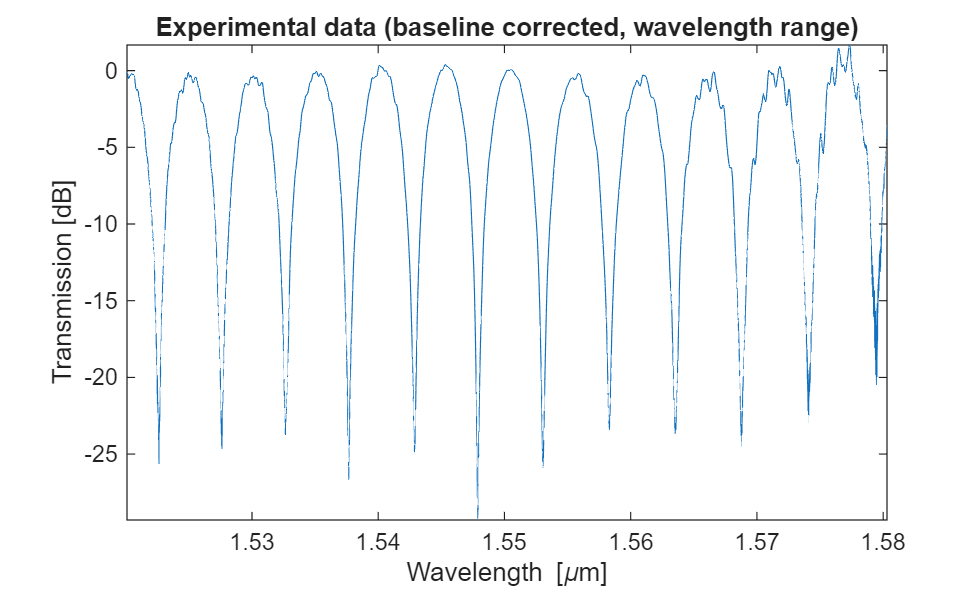

% Enter the Dropbox URL here.  Make sure it has a =1 at the end:
url = 'https://www.dropbox.com/s/1rvjfef4jqybc12/ZiheGao_MZI2_271_Scan1.mat?dl=1';
dL = 111.915;  % [micron] Path length difference in the MZI

%url = 'https://www.dropbox.com/s/zojmleq3gu77dsw/ZiheGao_MZI17_265_Scan1.mat?dl=1';
%dL = 219.366;

PORT=1; % Which Fibre array port is the output connected to?

a=websave('mzi.mat',url); % get data from Dropbox
load('mzi.mat');

% Data is stored in variable "scanResults".
% There are two columns - wavelength (1), and amplitude (2)
lambda=scanResults(1,PORT).Data(:,1)/1e9;
amplitude=scanResults(1,PORT).Data(:,2);

% Curve fit data to a polynomial for baseline correction
p=polyfit((lambda-mean(lambda))*1e6, amplitude, 4);
amplitude_baseline=polyval(p,(lambda-mean(lambda))*1e6); 

% Perform baseline correction to flatten the spectrum
% Use the curve polynomial, and subtract from original data
amplitude_corrected = amplitude - amplitude_baseline;
amplitude_corrected = amplitude_corrected + max(amplitude_baseline) - max(amplitude);

% data only within the wavelength range of interest.
lambda_min = min(lambda);	% Can limit the analysis to a range of wavelengths
lambda_max = max(lambda);   %  if the data on the edges is noisy
lambda_max = 1.57e-6;
lambda1=lambda_min:min(diff(lambda)):lambda_max;
amplitude=interp1(lambda, amplitude_corrected, lambda1,'linear');
lambda=lambda1;
amplitude(find(amplitude==-inf))=-50;  % check if there are -infinity data points

% plot baseline corrected spectrum
figure;
plot (lambda*1e6, amplitude);
xlabel ('Wavelength [\mum]');
ylabel ('Transmission [dB]');
axis tight
title ('Experimental data (baseline corrected, wavelength range)');

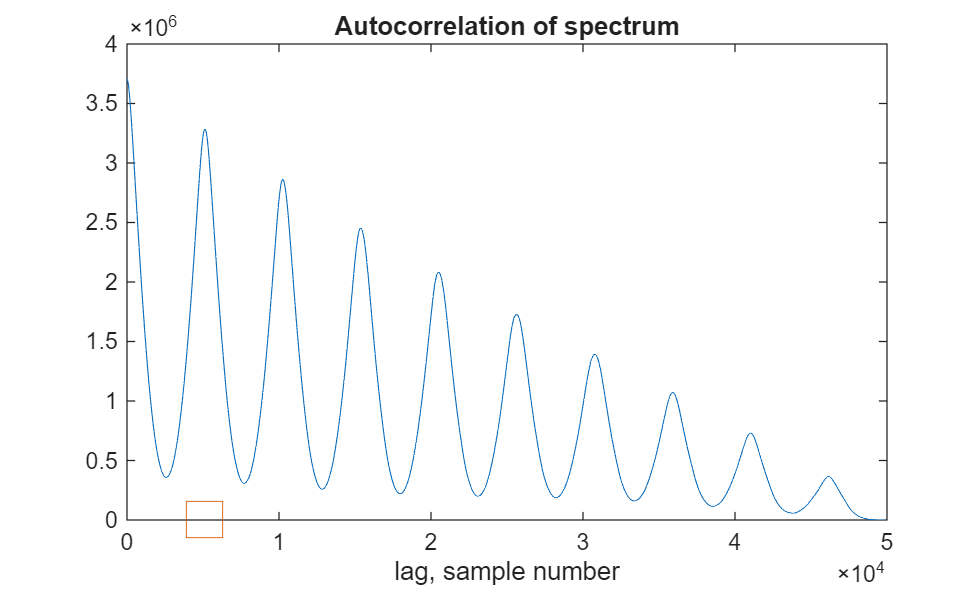



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Find ng from autocorrelation-based frequency estimation of spectrum
% auto-correction
[r,lags]=xcorr(amplitude); 
r=r(ge(lags,0));
lags=lags(ge(lags,0));
figure
plot(lags,r);
% estimate the frequency
d=diff(r);
start = find(gt(d,0)); start=start(1);
[peak_m, peak_i]=max(r(start:end));
peak_i=peak_i+start;  % location of the 1st peak in the autocorrelation
hold on;
plot(peak_i,0,'s','MarkerSize',20);
title ('Autocorrelation of spectrum')
xlabel('lag, sample number');


fsr = peak_i * mean(diff(lambda))

fsr = 5.1300e-09

ng_av = mean(lambda)^2/(dL*1e-6)/fsr

ng_av = 4.1580

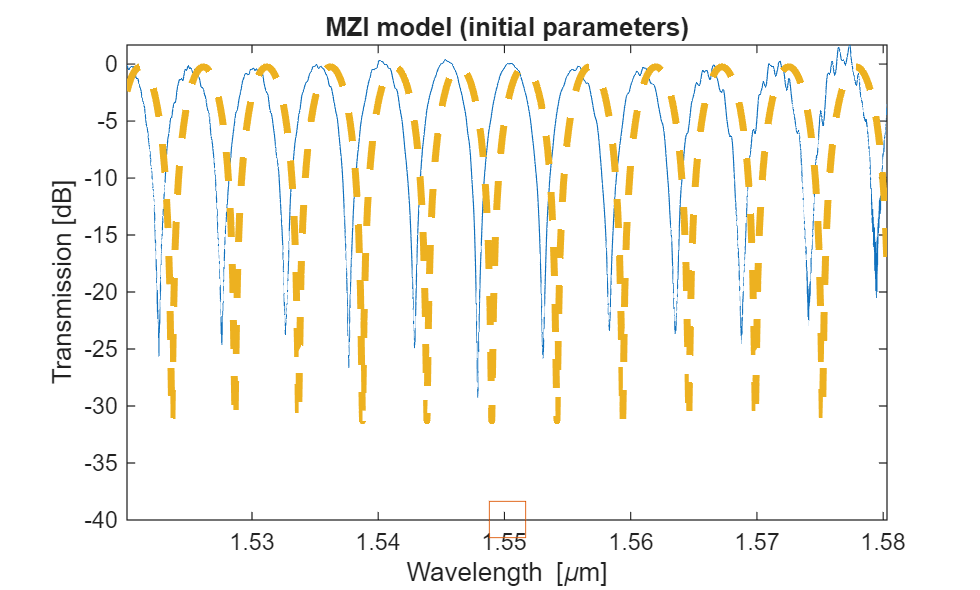



% find starting point for curve fitting, using the ng value
% lambda0 is in microns.
lambda0 = mean(lambda) * 1e6;
n1=2.4;
%modeNumber = n1_initial * dL / lambda0 - 0.5;
%n1 = (2*floor(modeNumber)+1)*lambda0/2/dL;
n2 = (n1-ng_av)/lambda0;
nx_init = [n1 n2 0];
alpha_init = 1e-3;  % propagation loss [micron^-1]
x0=[nx_init, alpha_init, 0];


% Define the MZI transfer function
% - as a Taylor expansion around the central wavelength
% - Use units of [microns] – keeps the variables closer to 1.
% - These make the curve fitting easier.
% use Matlab anonymous functions
% effective index:
neff = @(nx, lambda) ...
		(nx(1) + nx(2).*(lambda-lambda0) + nx(3).*(lambda-lambda0).^2); 
% neff([2.4, -1, 0], 1.56)  % test it.
% alpha = 1e-3;  % propagation loss [micron^-1]
% complex propagation constant
beta = @(nx, alpha, lambda) ...
		(2*pi*neff(nx, lambda)./lambda - 1i*alpha/2*ones(1,length(lambda)) );
% beta([2.4, -1, 0], 1e-3, [1.56, 1.57]) % test it.
% MZI transfer function
T_MZI = @(X, lambda) ...
        (10*log10( 0.25* abs(1+exp(-1i*beta(X(1:3), X(4), lambda)*dL)).^2) +X(5) );
% T_MZI([2.4, -1, 0, 1e-3], [1.56, 1.57]) % test it.


figure;
plot (lambda*1e6, amplitude);
hold all;
plot (lambda0, -40,'s','MarkerSize',20);
plot(lambda*1e6, T_MZI(x0, lambda*1e6),'--','LineWidth',3);
xlabel ('Wavelength [\mum]');
ylabel ('Transmission [dB]');
axis tight
title ('MZI model (initial parameters)');

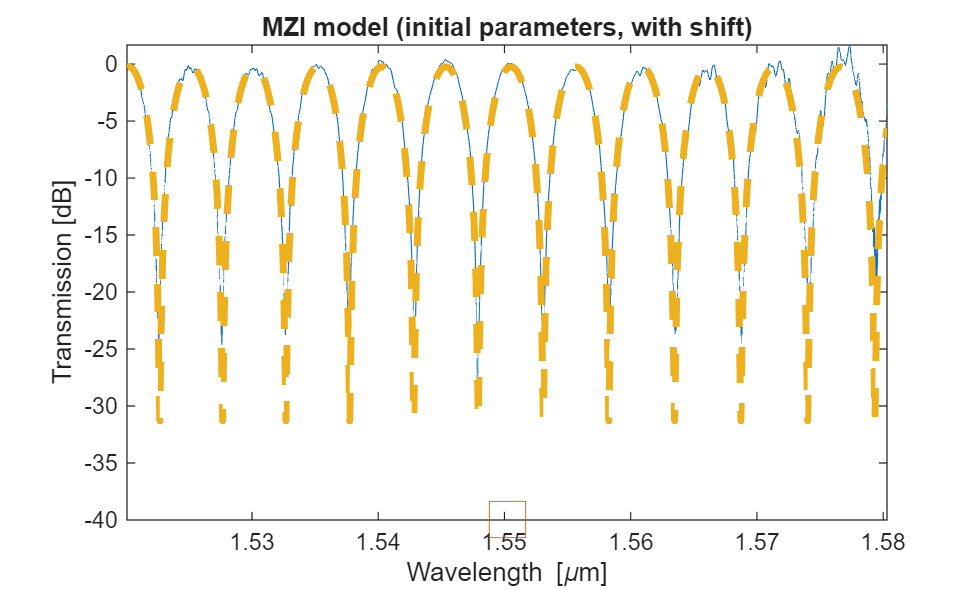



% Autocorrelation again, to find the shift between the fit function and experimental data
[r,lags]=xcorr(amplitude, T_MZI(x0, lambda*1e6)); 
r=r(ge(lags,0));
lags=lags(ge(lags,0));
[peak_m, peak_i]=max(r);
lambda_offset = peak_i(1) * mean(diff(lambda));
n_shift = lambda_offset*lambda0/fsr/dL;
x0(1)=x0(1)+n_shift;

figure;
plot (lambda*1e6, amplitude);
hold all;
plot (lambda0, -40,'s','MarkerSize',20);
plot(lambda*1e6, T_MZI(x0, lambda*1e6),'--','LineWidth',3);
xlabel ('Wavelength [\mum]');
ylabel ('Transmission [dB]');
axis tight
title ('MZI model (initial parameters, with shift)');



% Curve fit:  
[xfit,resnorm] = lsqcurvefit(T_MZI,x0,lambda*1e6,amplitude);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


xfit

xfit =     2.4030   -1.1380   -0.0112    0.0022    0.2992


r=corrcoef(amplitude,T_MZI(xfit, lambda*1e6));
r2=r(1,2).^2

r2 = 0.9906

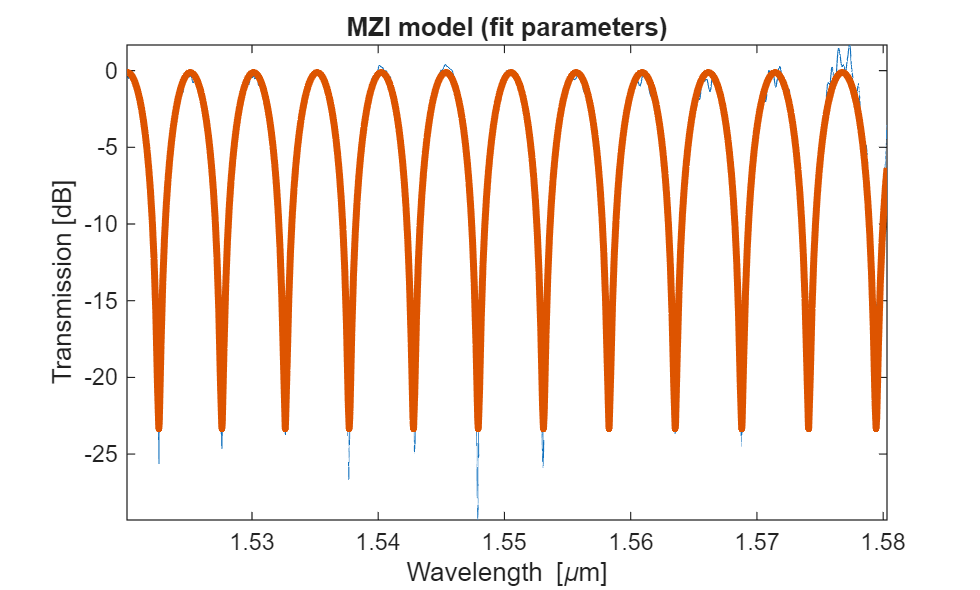


figure;
plot (lambda*1e6, amplitude);
hold all;
plot(lambda*1e6, T_MZI(xfit, lambda*1e6),'LineWidth',3); 
xlabel ('Wavelength [\mum]');
ylabel ('Transmission [dB]');
axis tight
title ('MZI model (fit parameters)');

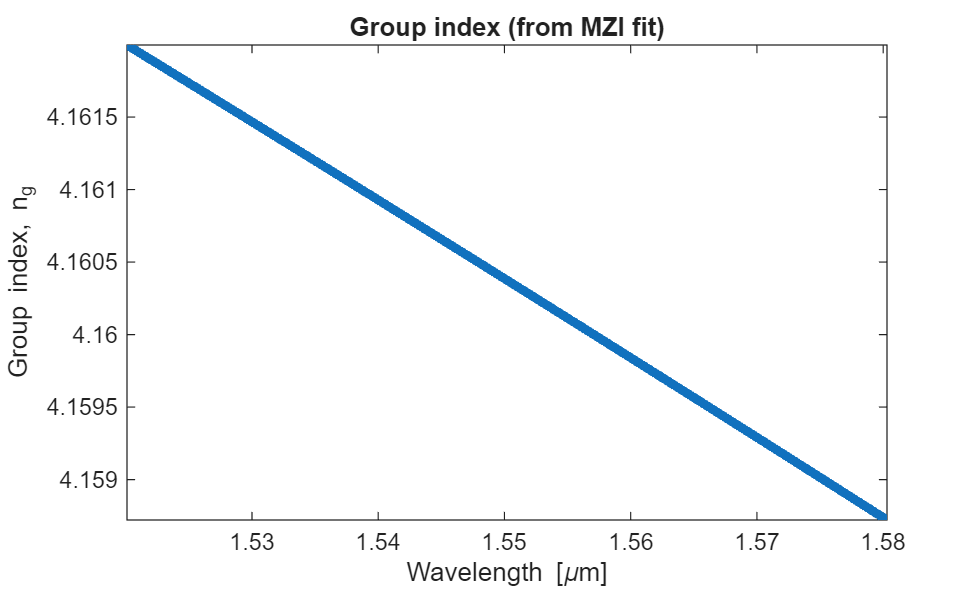

ng0 = 4.1612


% Check if the fit is good.  If so, find ng
if (ge(r2,0.8))
  % plot ng curve
  figure;
  neff_fit = neff(xfit(1:3),lambda*1e6);
  dndlambda=diff(neff_fit)./diff(lambda); dndlambda=[dndlambda, dndlambda(end)];
  ng=(neff_fit - lambda .* dndlambda);
  plot(lambda*1e6, ng, 'LineWidth',4);
  xlabel ('Wavelength [\mum]');
  ylabel ('Group index, n_g');
  axis tight
  title ('Group index (from MZI fit)');
    
  % waveguide parameters at lambda0
  ng0 = xfit(1) - lambda0*xfit(2)
end

## Check

assert(ge(r2,0.8), 'The goodness of it is low.')

The goodness-of-fit is low.  The R^2 value should be greater than 0.8.  Adjust the initial conditions until the fit quality is higher.

Make sure you have a variable named `r2` for the check to work properly.